# Carbon Neutral

[⇦ Return to the navigation page](matlab:run("Navigation.mlx"))

to address the challenges of climate change, many company, such as Mathworks, commited themselves to becoming carbon neutral. A fundamental component of this efforts is supporting the development of renewable energy. In this scripts, we will explore two renewable energy sources based on fluid system: hydropower and wind turbine.

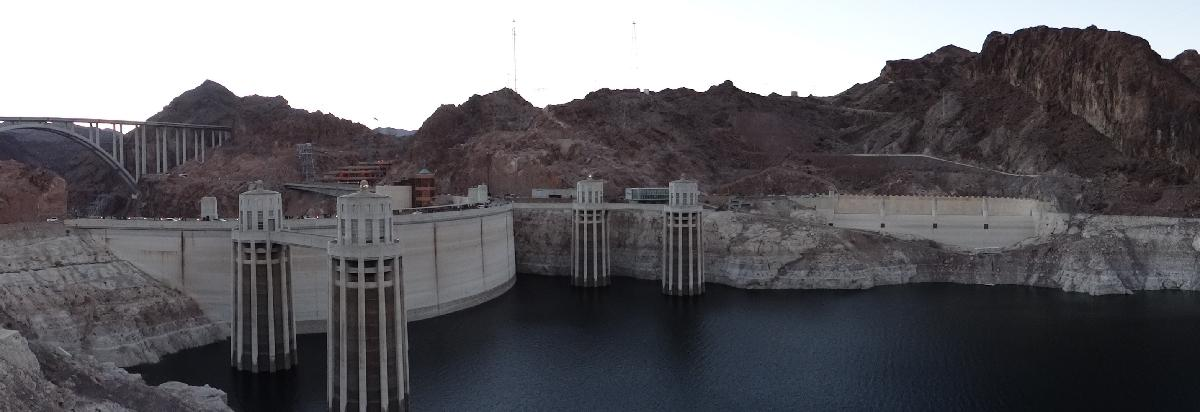

Hoover Dam intake tower from lake Mead, [USGS](https://www.usgs.gov/media/images/hoover-dam-intake-towers-panorama)

## Introduction

Fluid dynamics plays a significant role in the development and optimizaton of renewable energy technologies. For exmple the performance of a wind turbine is heavily influenced by the aerodynamic properties of the blades, fluid dynamics simulation are usually carried to optimized parameters such as the shape, size and angle of attack of the blades. 

In this script we will study wind turbine and hydroelectric power to generate enough electricity to power the data center running MATLAB Online.

### What is energy?

In a fluid, energy refers to the ability of a fluid to produce work. It takes various form:

- Kinetic energy refers to the energy of motion

- Potential energy refers to the energy associated with a conservative external fields such as gravity

- Internal energy refers to the molecular internal energy of the fluid

  **Try. **Following the prompt from `unitInfo`, explore all unit of pressure available

unitInfo("Energy")


All units of dimension 'Energy':

erg - erg
eV - electronvolt
E_h - Hartree energy 
J - joule ['SI']
kpm - kilopond meter
Wh - watt hour
Ws - watt second

Get the base SI units of any unit above by calling rewrite(<unit>,'SI').
SI units accept all SI prefixes. For details, see SI Unit Prefixes List.



### What is power?

Power refers to the rate at which energy is transferred. It is typically measured in units of energy per unit of time, such as Watts (W) or horsepower (hp).

  **Try. **Following the prompt from `unitInfo`, explore all unit of pressure available

unitInfo("Power")


All units of dimension 'Power':

HP_DIN - metric horsepower (DIN 66036)
HP_E - electrical horsepower
HP_I - mechanical horsepower
HP_UK - British imperial horsepower
poncelet - poncelet
PS_DIN - horsepower (DIN 70020)
PS_SAE - net horsepower (SAE J1349)
W - watt ['SI']

Get the base SI units of any unit above by calling rewrite(<unit>,'SI').
SI units accept all SI prefixes. For details, see SI Unit Prefixes List.



### Need analysis

[PICTURE DATA CENTER]

For this script we will consider that MATLAB Online is run on data center located in Natick, MA. The maximum power consumption of this data center is 1300 kW and its power usage in 2022 is the following :

  **Try. **Load and visualize the power consumption of the data center during 2022

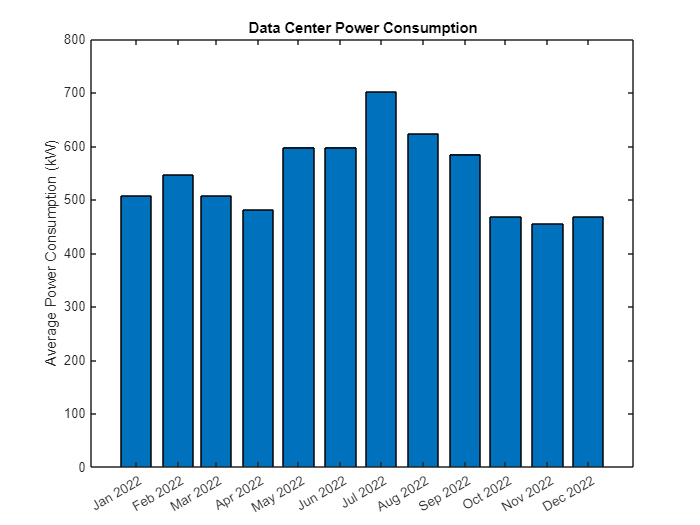

load DataCenter.mat
bar(dataCenter.date,dataCenter.avgPower)
ylabel("Average Power Consumption (kW)")
title("Data Center Power Consumption")

**Remark: **The data presented here are all fictional and do not represent the reality of the power consumed by MathWorks data center.

 **Exercise. **Add a data entry in `dataCenter` corresponding to the total energy consumed during this month in kWh.

u = symunit;
dataCenter.energyUsage = dataCenter.avgPower.*dataCenter.numberOfDay * 24;
annualEnergyUsage = sum(dataCenter.energyUsage) * u.kW * u.h

$$annualEnergyUsage = 4774848\,h\,\mathrm{kW}$$

 **Reflect**. A microwave would consume about 1 kWh of electrical energy for each hour it runs.

 **Reflect**. The average american household consum around 10,000 kWh electrical energy each year. Reflect on the energy consumption compare to a regular household.

## Understanding Wind Turbine

In this section we are studying the efficiency and wind turbine and will estimate the number of wind turbine required to cover the data center power consumption .

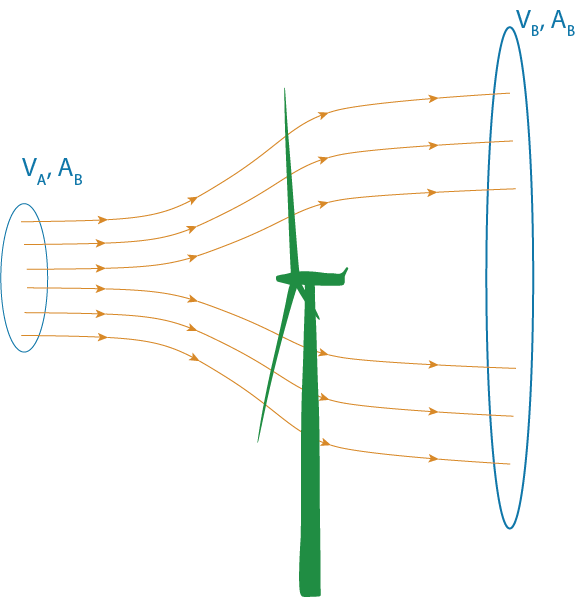

A power turbine of surface $S_t$, generates power by collecting the kinetic enegy from upstram air flow at velocity $v_A$ (m/s). The air flow is slowed down and exit the system downstream at velocity $v_B$. The wind speed at the turbine is $v_t$. The first approach to study this system is to apply the mass and momentum conservation equation to the control volume that encompass the streamline as presented in the previous figure. If you need to practice or refresh your knowledge on the control volume method, you should attempt to complete [ManOnTheMoon.mlx](matlab:open('./ManOnTheMoon.mlx')).

### **Control Volume**

#### **Mass Conservation**

We consider the control volume as describe as in the previous figure. All the mass flow coming in the control volume volume through the surface A, must exit the control volume through surface B. Therefore we can write the following mass flow equilibrium:


$$\rho S_A v_A = \rho S_B v_B = \rho S_t v_t = \dot{m}$$


where $\rho$ is the density, $(S_A,S_B,S_t)$ are the arar of surface A, B and the area of the turbine, and $(v_A,v_B,v_t)$ are the velocity of the flow through the surface A, B and the turbine itself.

  **Try. **Define the problem parameters (velocity, areas) and compute the mass flow through the turbine.

syms rho_air S_upstream S_downstream S_turbine...
    V_upstream V_downstream V_turbine
massFlow = rho_air*S_turbine*V_turbine

$$massFlow = S_{\mathrm{turbine}}\,V_{\mathrm{turbine}}\,\rho_{\mathrm{air}}$$

#### **Momentum Conservation**

The momentum conservation equation can be expressed as:


$$\underbrace{\frac{\partial}{\partial t}\int_{CV}\rho\vec{u} \; dV}_\text{Acceleration}
+
\underbrace{\int_{CS}(\vec{u}\cdot\vec{n})\rho\vec{u} \; dS}_\text{Thrust}
=
\sum\vec{F}$$


We are considering the flow to be at steady-state, so the derivative with respect to time is equal to zero. There is no radial flow, so all the air entering the turbine upstream is exiting the turbine downstream. Therefore, we are left with:


$$\int_\text{upstream}(\vec{v_A}\cdot\vec{n_A})\rho\vec{v_A} \; dS
+
\int_\text{downstream}(\vec{v_B}\cdot\vec{n_B})\rho\vec{v_B} \; dS
=
\vec{F}_\text{turbine\rightarrow air}$$


We are considering that the problem is one-dimensional along the horizontal axis:


$$\int_\text{upstream}(\vec{v_A}\cdot\vec{n_A})\rho v_A \; dS
+
\int_\text{downstream}(\vec{v_B}\cdot\vec{n_B})\rho v_B \; dS
=
F_\text{turbine\rightarrow air}$$


The upstream term can be expressed as:


$$\int_\text{upstream}(\vec{v}\cdot\vec{n})\rho v \; dS
=
-\dot{m}v_A$$


 **Exercise. **Express the downstram term and compute the total force by the turbine on the air in `F_ta`. Compute `F_at` the reciprocal force of the air on the turbine.

F_TurbineOnAir = -massFlow*V_upstream + massFlow*V_downstream;
F_AirOnTurbine = - F_TurbineOnAir

$$F\_AirOnTurbine = S_{\mathrm{turbine}}\,V_{\mathrm{turbine}}\,V_{\mathrm{upstream}}\,\rho_{\mathrm{air}}-S_{\mathrm{turbine}}\,V_{\mathrm{downstream}}\,V_{\mathrm{turbine}}\,\rho_{\mathrm{air}}$$

F_AirOnTurbine = simplify(F_AirOnTurbine)

$$F\_AirOnTurbine = -S_{\mathrm{turbine}}\,V_{\mathrm{turbine}}\,\rho_{\mathrm{air}}\,\left(V_{\mathrm{downstream}}-V_{\mathrm{upstream}}\right)$$

The elemental energy exchange captured by the turbine is:


$$dE = F_\text{air\rightarrow turbine}dx$$


We can express the power by:


$$P_\text{air\rightarrow turbine}=\frac{dE}{dt} = \frac{d(F_\text{air\rightarrow turbine}dx)}{dt}=\frac{dF_\text{air\rightarrow turbine}}{dt}dx + F_\text{air\rightarrow turbine}\frac{dx}{dt}$$


We are considering the force to be constant with time, therefore:


$$P_\text{air\rightarrow turbine} = F_\text{air\rightarrow turbine}\frac{dx}{dt}$$


Thus,


$$P_\text{air\rightarrow turbine}=F_\text{air\rightarrow turbine}v_t$$


 **Exercise. **Compute the power of the collected by the turbine.

Power_AirOnTurbine = simplify(F_AirOnTurbine*V_turbine)

$$Power\_AirOnTurbine = -S_{\mathrm{turbine}}\,{V_{\mathrm{turbine}}}^{2}\,\rho_{\mathrm{air}}\,\left(V_{\mathrm{downstream}}-V_{\mathrm{upstream}}\right)$$

### Power Balance

We can also express the power collected by the turbine by performing a balance of power on the system. Because we are consedering no radial flow, the power is only exchange axially, meaning that the difference of power from the upstream to downstream must be equal to the power collected by the turbine.


$$P_\text{air\rightarrow turbine} = P_A - P_b \quad\quad (\clubsuit)$$


 **Exercise. **Compute the expression of the power available at surface $S_A$ and $S_B$

Power_upstream = 0.5*massFlow*V_upstream^2;
Power_downstream = 0.5*massFlow*V_downstream^2;

 **Exercise. **Write $(\clubsuit)$ in `PowerBalance.`

PowerBalance = Power_AirOnTurbine == Power_upstream - Power_downstream

$$PowerBalance = -S_{\mathrm{turbine}}\,{V_{\mathrm{turbine}}}^{2}\,\rho_{\mathrm{air}}\,\left(V_{\mathrm{downstream}}-V_{\mathrm{upstream}}\right)=0.5000\,S_{\mathrm{turbine}}\,V_{\mathrm{turbine}}\,{V_{\mathrm{upstream}}}^{2}\,\rho_{\mathrm{air}}-0.5000\,S_{\mathrm{turbine}}\,{V_{\mathrm{downstream}}}^{2}\,V_{\mathrm{turbine}}\,\rho_{\mathrm{air}}$$

 **Exercise. **Solve the power balance $(\clubsuit)$ to express $V_t$

V_solution = solve(PowerBalance, V_turbine)

$$V\_solution = \left(\begin{array}{c} 0\\ 0.5000\,V_{\mathrm{downstream}}+0.5000\,V_{\mathrm{upstream}} \end{array}\right)$$

 **Exercise. Substitute **$V_t$ for its correct solution function of $V_A$ and $V_B$ in the epression of the power of the air on the turbine

Power_AirOnTurbine = subs(Power_AirOnTurbine,V_turbine, V_solution(2))

$$Power\_AirOnTurbine = -S_{\mathrm{turbine}}\,\rho_{\mathrm{air}}\,{\left(0.5000\,V_{\mathrm{downstream}}+0.5000\,V_{\mathrm{upstream}}\right)}^{2}\,\left(V_{\mathrm{downstream}}-V_{\mathrm{upstream}}\right)$$

The power collected by the turbine is now a function of the upstream and downstream velocity.

### Wind turbine efficiency

In this subsection, we are studying the efficiency of the wind turbine. The efficiency can be expressed as the ratio in between the power collected by the turbine over the maximum power available to the turbine $\eta = \frac{P_\text{turbine }}{P_\text{max}}$.

The maximum available to the turbine should be equal to the power of the wind going to the surface of turbine if the turbine was not even built.

 **Exercise. **Define the maximum power that is available to the wind turbine.

Power_max = 0.5*S_turbine*rho_air*V_upstream^3

$$Power\_max = 0.5000\,S_{\mathrm{turbine}}\,{V_{\mathrm{upstream}}}^{3}\,\rho_{\mathrm{air}}$$

 % Add a check my answer here
  

 **Exercise. **Define the efficiency of the wind turbine

eta_turbine = Power_AirOnTurbine/Power_max

$$eta\_turbine = -\frac{2\,{\left(0.5000\,V_{\mathrm{downstream}}+0.5000\,V_{\mathrm{upstream}}\right)}^{2}\,\left(V_{\mathrm{downstream}}-V_{\mathrm{upstream}}\right)}{{V_{\mathrm{upstream}}}^{3}}$$

The power efficiency of the wind turbine only depends on two parameters, the upstream and downstream velocity. However, we also know that the downstream velocity is necessarly lower than the upstream velocity and both velocity are greater than zero. Therefore, we can study the efficiency of the turbine as a function of a parameter $x = \frac{V_\text{downstream}}{V_\text{upstream}}$, the ratio of velocity in between the downstream and upstream velocity. This parameter represents how much the air flow is slowed down by the wind turbine.

  **Try. **Run the following lines of code to express the efficiency of the turbine as a function of the parameter $x$.

% Substitute v_B by x*v_A, this should rewrite the equation as a function
% of x = v_B/v_a
syms x
eta_turbine = simplify(subs(eta_turbine, V_downstream, x*V_upstream))

$$eta\_turbine = -0.5000\,\left(x-1\right)\,{\left(x+1\right)}^{2}$$

  **Try. **Plot the the wind turbine efficiency as a function of parameter $x$.

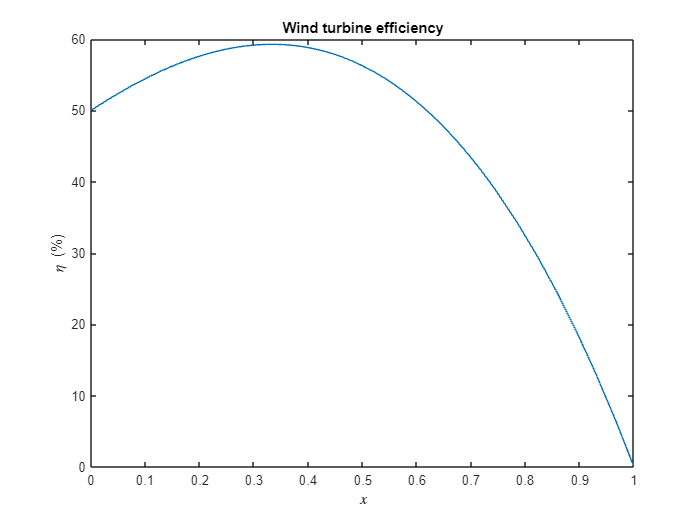

% Plotting function
fplot(x,100*eta_turbine,[0 1])
xlabel("$x$",Interpreter="latex")
ylabel("\eta (%)")
title("Wind turbine efficiency")

 **Reflect**. The efficincy of the wind turbine presents a maximum, slowing down the upstream flow too much will not results in greater energy conversion. In fact, the ratio of velocity presenting the highest efficiency is 1/3, for an efficency of around 59%. This limit is known as Betz's limit.

### Design

Now that we know how much energy can be extracted by a wind turbine, we can use weather data from a weather station in Natick, MA to determine the energy that could potentially be collected by a wind turbine in this location.

  **Try.** Loas and visualize the weather data.

load NatickWeather.mat
weather

weather = 365×5 timetable
       time          Temp       Wind        RH      Rainfall    DewPoint
    ___________    ________    _______    ______    ________    ________
    01-Jan-2022      8.2611    0.44726    93.385     1.9558      6.9381 
    02-Jan-2022      5.5826     1.0795    91.463     3.6322      3.8752 
    03-Jan-2022     -3.5184     2.6574    63.033     0.2794     -10.912 
    04-Jan-2022     -4.2253     1.7413    49.112          0     -14.403 
    05-Jan-2022      3.0132     1.8485    89.962     6.4262      1.0056 
    06-Jan-2022      1.9187     1.4706    73.631          0     -3.3551 
    07-Jan-2022     -2.2704      1.632    85.014          0     -5.

 **Exercise. **What is the time step of the data collected by the weather station (don't forget the unit!)

timeStep = 1 * u.day;
% check answer
 

  **Try.** Use the following slider to define the wing span (???) of the wind turbine, a quick online search could tell give you a good idea of how big in-land wind turbine are.

turbineWingSpan = 70* u.meter;
S_turbine = pi*turbineWingSpan^2/4;
rho_air = 1.14*u.kg/u.meter^3;

We will consider that over the wind turbine global efficiency is inferior to the Betz's limit at $\eta=50\%$. 

 **Exercise. **Using the dot notation, add a column to the weather table corresponding the the power extracted from the wind $P=\frac{\eta}{2}\rho S_t V_\text{wind}^3$

weather.powerExtracted = 0.5/2*rho_air*S_turbine*(weather.Wind*u.m/u.s).^3;
% Check Answer
 

  **Try.** Based on your previous answer, we can compute the energy that is generated each day, the annual energy production and so the number of wind turbine that would need to be installed to power the data center.

% Compute the daily and annual energy produced by the wind turbine
weather.dailyProduction = weather.powerExtracted * 1*u.day;
turbineAnnualProduction = sum(weather.dailyProduction)

$$turbineAnnualProduction = 4.3200e+06\,\frac{d\,\mathrm{kg}\,m^{2}}{s^{3}}$$

% Rewrite this energy in more common enregy unit, kWh
turbineAnnualProduction = rewrite(turbineAnnualProduction, [u.kW u.h])

$$turbineAnnualProduction = 1.0368e+05\,h\,\mathrm{kW}$$

% Compute the number of wind turbine that would need to be installed
numberOfTurbine = annualEnergyUsage/turbineAnnualProduction

$$numberOfTurbine = 46.0537$$

 **Reflect**. Acceptability? Link to mathworks wind turbine farm in Oklahoma

## Understanding Hydropower

A second option is considered to power the data center is to build a retention lake collecting rainwater from the area to generate hydroelectric power.

### Mathematical modelling of the retention lake

plotRetentionLake

 **Exercise. **Compute the total energy that such data center would be using

annualEnergy = avgAnnualPower * u.year

 **Exercise. **Convert this energy use in kWh

annualEnergy = unitConvert(annualEnergy,u.kW*u.hour)

### Option 2: Build a large rainwater retention lake

DeltaP = 9.81*1000*10*u.Pa 
VolumeWater = totalEnergy/DeltaP;
VolumeWater = unitConvert(VolumeWater,u.m^3)
AnnualPrecipitation = 1.11*u.m;
SurfaceCaptation = VolumeWater/AnnualPrecipitation
SurfaceCaptation = unitConvert(SurfaceCaptation,u.km^2)

MathWorks is actually going to Solar and Wind instead: [MathWorks Carbon Neutral Innitiative](https://www.mathworks.com/company/aboutus/carbon-neutral.html)

## Modeling power generated from a retention lake

### Introduction

lengthLake = 100*u.m;
surfaceLake = lengthLake^2
waterDensity = 1000*u.kg/u.m^3;
surfaceCaptation = 100 * surfaceLake;
plotRetentionLake()

### Mathematical model


$$\displaystyle\frac{\partial}{\partial t}\int_{CV}\rho \; dV+\int_{CS} (\vec{u}\cdot\vec{n})\rho \; dS = 0$$



$$\rho S_\text{res}\frac{dh_\text{res}}{dt} = \dot{m}_\text{rain}-\dot{m}_\text{evap}-\dot{m}_\text{turbine}$$


### Model the rainfall

load NatickWeather.mat
weather

% Retime timetable
dailyWeather = retime(weather(:,[1 2 3 5 6]),"regular","mean",...
    "TimeStep",caldays(1));

% Retime each override variable to same time vector
TT = retime(weather(:,"Rainfall"),dailyWeather.Properties.RowTimes,"sum");
dailyWeather = addvars(dailyWeather,TT.(1),'Before',4,...
    'NewVariableNames',"Rainfall");
clear TT

% Display results
dailyWeather

% totalMassRainfall = sum(weather.mrain*)

### Model evaporation

## Helper Functions

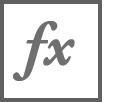`plotRetentionLake()`

function plotRetentionLake()
    Z = membrane(1,10);
    Z = [[fliplr(Z) Z]; flipud([fliplr(Z) Z])];
    n = size(Z,1);
    [X,Y] = meshgrid(0:n-1,0:n-1);
    X = 2*X/(n-1) - 1;
    Y = 2*Y/(n-1) - 1;
    C = zeros(size(Z));
    C(11:31,11:31) = 1.0;
    Z(1,:) = 0.0;
    Z(end,:) = 0.0;
    Z(:,1) = 0.0;
    Z(1,end) = 0.0;
    Z( Z < 0 ) = 0.0;
    X = X * 100;
    Y = Y * 100;
    s = surf(X,Y,Z,C,"FaceColor","flat","EdgeColor","k");
    view([-64 59])
    mapFace = [0.3 0.3 0.3
               0.83 0.94 0.97];
    colormap(mapFace)
end

[⇦ Return to the navigation page](matlab:run("Navigation.mlx"))

Copyright 2023 The MathWorks™, Inc